% Img=rgb2gray(imread("a.png"));
% 
% whos Img
% 
% %[M,N]=size(Img);
% %Img = Img(:,1:M)
% 
% figure
% imshow(Img)
% 
% figure
% fourier = fft2(Img);
% 
% %fourier = Img;
% f2 = abs(fftshift(fourier));
% imshow(im2uint8(mat2gray(log(double(abs(f2)+0.003)))),[])
% colormap gray
% 
% [M,N]=size(Img);
% 
% %Img = Img(:,1:M);
% D0 =10;
% % M = D0*2+1;
% % N = M;
% D = double(zeros(M,N));
% H = double(zeros(M,N));
% P=floor(M/2);
% Q=floor(N/2);
% 
% for u=1:M
%     for v=1:N
%         D(u,v)=((u-P)^2+(v-Q)^2)^0.5;
%         if(D(u,v)<=D0)
%             H(u,v)=1;
%         else
%             H(u,v)=0;
%         end
%     end
% end
% 
% %H=H(1:M-1,1:N-1);
% 
% %H=H/(sum(sum(H)));
% %imshow(H)
% H=1-H;
% H = ifft2(H);
% imshow(H)
% 
% fourier = H.*fourier;
% ifourier = ifft2(fourier);
% 
% imagesc(abs(fftshift(ifourier)))
% colormap gray


%H=H/(sum(sum(H)));

H1 = fft2(H);
imshow(abs(fftshift(H1)),[])
fourier = H1.*fourier;
ifourier = ifft2(fourier);

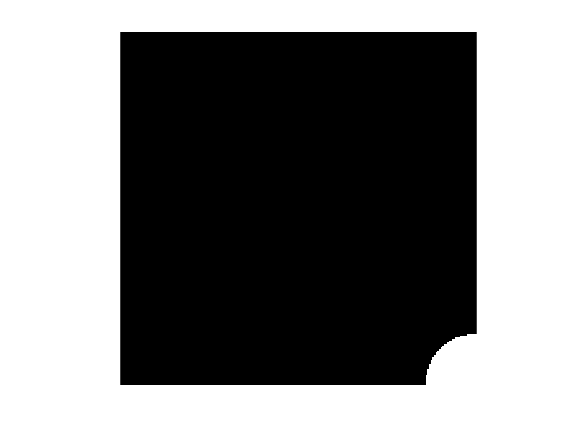

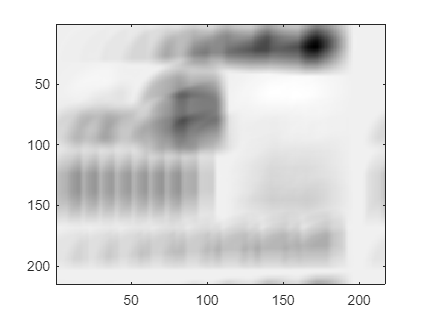

Img=rgb2gray(imread("a.png"));

figure
imshow(Img)

figure
fourier = fft2(Img);

imagesc(abs(fftshift(fourier)))
colormap gray

%[M,N]=size(Img);

%Img = Img(:,1:M);
D0 = 90;
M = D0*2+1;
N = M;
D = double(zeros(M,N));
H = double(zeros(M,N));
P=floor(M/2);
Q=floor(N/2);

for u=1:M
    for v=1:N
        D(u,v)=((u-P)^2+(v-Q)^2)^0.5;
        if(D(u,v)<=D0)
            H(u,v)=1;
        else
            H(u,v)=0;
        end
    end
end

%h = ifft2(H);
imshow(H)

fourier=filter2(H,fourier);
ifourier = ifft2(fourier);

imagesc(abs(fftshift(ifourier)))
colormap gray
ul=filter2(abs(fftshift(ifourier)),Img);
imshow(ul,[])

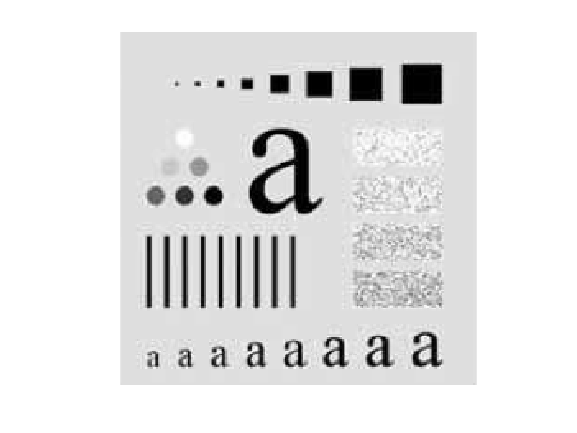

Img=rgb2gray(imread("a.png"));

figure
imshow(Img)


figure
fourier = fft2(Img);

%fourier = Img;

imagesc(abs(fftshift(fourier)))
colormap gray

%[M,N]=size(Img);

%Img = Img(:,1:M);
D0 = 10;
M = D0*2+1;
N = M;
D = double(zeros(M,N));
H = double(zeros(M,N));
P=floor(M/2);
Q=floor(N/2);

for u=1:M
    for v=1:N
        D(u,v)=((u-P)^2+(v-Q)^2)^0.5;
        if(D(u,v)<=D0)
            H(u,v)=1;
        else
            H(u,v)=0;
        end
    end
end

%H=H(1:M-1,1:N-1);

H=H/(sum(sum(H)));
H = ifft2(H);
imshow(H)

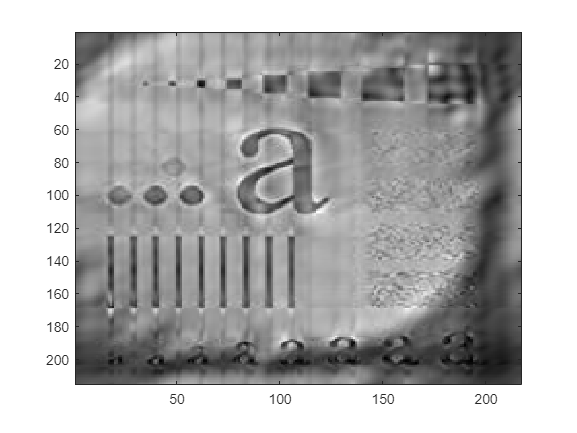


fourier=filter2(H,fourier);
ifourier = ifft2(fourier);

imagesc(abs(ifourier))
colormap gray

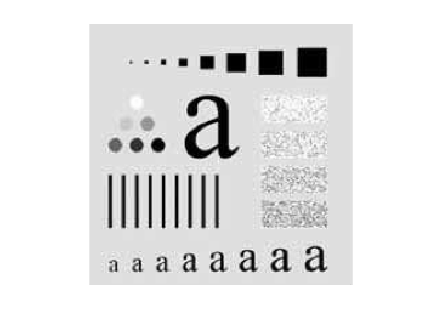

clc;
clear;
close all;

Img=rgb2gray(imread("a.png"));

figure
imshow(Img)

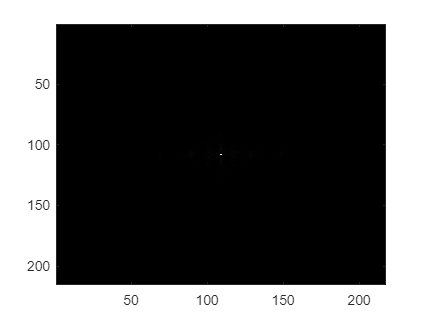

figure
fourier1 = fft2(Img);

%fourier = Img;

imagesc(abs(fftshift(fourier1)))
colormap gray

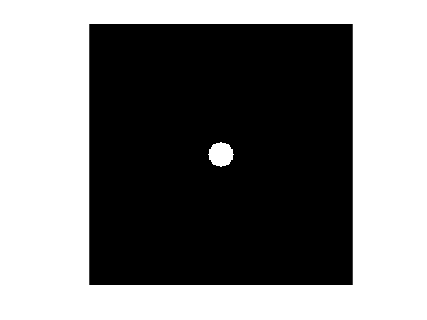


[M,N]=size(Img);

%Img = Img(:,1:M);
D0 = 10;
% M = D0*2+1;
% N = M;
P=floor(M/2);
Q=floor(N/2);
D = double(zeros(P,Q));
H = double(zeros(P,Q));


for u=0:M-1
    for v=0:N-1
        D(u+1,v+1)=((u-P)^2+(v-Q)^2)^0.5;
        if(D(u+1,v+1)<=D0)
            H(u+1,v+1)=1;
        else
            H(u+1,v+1)=0;
        end
    end
end

imshow(H,[])

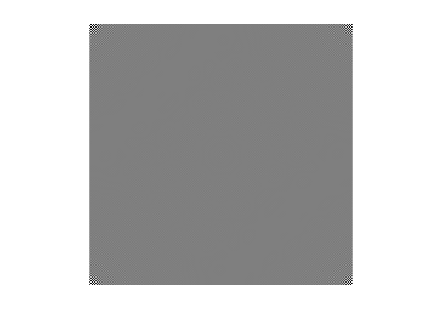

h = ifft2(H);
imshow(h,[])

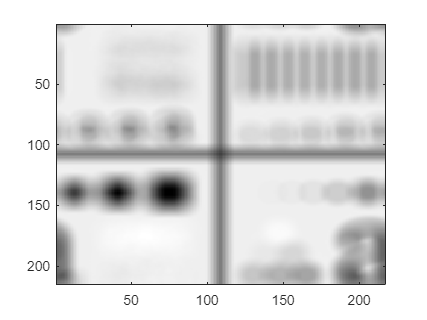

fourier=filter2(H,Img);
imagesc(abs(fftshift(fourier)))